**Nguyen Tien Thanh -S3818111**

clearvars
close all
clc

**Exercise 4A**

Section 1 alpha=10 beta=20 gamma=30 and APB=[1,2,3]'

Calculate transformation matrix

ATB=ARB*BP

%% Section A
disp('Exercise 4')

Exercise 4


disp('Section A')

Section A


disp('section i')

section i


disp('alpha=10 beta=20 gamma=30')

alpha=10 beta=20 gamma=30


% Transformation matrix=ARB*BP
ATB1=transl(1,2,3)*(trotz(10,'deg')*troty(20,'deg')*trotx(30,'deg'))

ATB1 =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


Section 2 beta=20 and APB=[1,0,1]'

Calculate transformation matrix

ATB=ARB*BP

disp('section ii')

section ii


disp('beta=20')

beta=20


% Transformation matrix=ARB*BP
ATB2=transl(3,0,1)*troty(20,'deg')

ATB2 =     0.9397         0    0.3420    3.0000
         0    1.0000         0         0
   -0.3420         0    0.9397    1.0000
         0         0         0    1.0000


**Exercise 4B**

Calculate AP=ATB*APB

Sketch results based on section 2

%%Section B
disp('section B')

section B


disp('Plot graph')

Plot graph


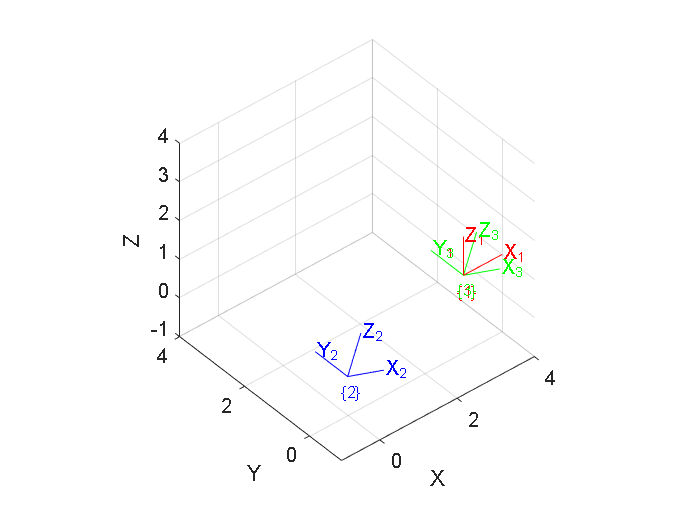

%Set boundary for the 3D plots from -1 to 4
plotvol([-1 4 -1 4 -1 4])
%translation [3;0;1]
T=transl(3,0,1);
%plot the graph with green frame 1
trplot(T, 'frame', '1', 'color', 'r') 
%rotation 20 degree
ARB=troty(20,'deg');
%plot the graph with blue frame 2
trplot(ARB, 'frame', '2', 'color', 'b') 
%transformation function
ATB=transl(3,0,1)*troty(20,'deg'); 
%plot the graph with green frame 3
trplot(ATB, 'frame', '3', 'color', 'g')
view([-40 40]) % View from -40 to 40


% Calculate AP relative to BP=[1;0;1]
disp('Calculate AP')

Calculate AP


AP=ATB*[1;0;1;1]

AP =     4.2817
         0
    1.5977
    1.0000


**Exercise 4C** 

Use matlab function and calculation to compare the inverse results by using identity matrix

ATB=TBA^-1=ARB',-ARB'*APB

Section 1 alpha=10 beta=20 gamma=30

%% Section C
disp('Section C')

Section C


disp('section i')

section i


disp('alpha=10 beta=20 gamma=30')

alpha=10 beta=20 gamma=30


% Transformation matrix
ATB_1=transl(1,2,3)*(trotz(10,'deg')*troty(20,'deg')*trotx(30,'deg'));

% Inverse using built in function inv
ATB_inverse_1=inv(ATB_1)

ATB_inverse_1 =     0.9254    0.1632   -0.3420   -0.2257
    0.0180    0.8826    0.4698   -3.1927
    0.3785   -0.4410    0.8138   -1.9380
         0         0         0    1.0000



% Inverse using symbolic fomula ATB=TBA^-1=ARB',-ARB'*APB
BRA_1 = ATB_1(1:3,1:3); APBorg_1 = ATB_1(1:3,4);
BTA_1 = [BRA_1' -BRA_1'*APBorg_1; 0 0 0 1]

BTA_1 =     0.9254    0.1632   -0.3420   -0.2257
    0.0180    0.8826    0.4698   -3.1927
    0.3785   -0.4410    0.8138   -1.9380
         0         0         0    1.0000



% Check answer by using identity matrix
identity_BTA_1=ATB_1*BTA_1

identity_BTA_1 =     1.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000         0   -0.0000
    0.0000         0    1.0000   -0.0000
         0         0         0    1.0000


identity_ATB_inverse_1=ATB_1/ATB_1 

identity_ATB_inverse_1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Section 2 beta=20

disp('section ii')

section ii


disp('beta=20')

beta=20


% Transformation matrix
ATB_2=transl(3,0,1)*troty(20,'deg');

% Inverse using built in function
ATB_inverse_2=inv(ATB_2)

ATB_inverse_2 =     0.9397         0   -0.3420   -2.4771
         0    1.0000         0         0
    0.3420         0    0.9397   -1.9658
         0         0         0    1.0000



% Inverse using symbolic fomula
BRA_2 = ATB_2(1:3,1:3); APBorg_2 = ATB_2(1:3,4);
BTA_2 = [BRA_2' -BRA_2'*APBorg_2; 0 0 0 1]

BTA_2 =     0.9397         0   -0.3420   -2.4771
         0    1.0000         0         0
    0.3420         0    0.9397   -1.9658
         0         0         0    1.0000



% Check answer by using identity matrix
identity_BTA_2=ATB_2*BTA_2

identity_BTA_2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


identity_ATB_inverse_2=ATB_2/ATB_2

identity_ATB_inverse_2 =     1.0000         0         0         0
         0    1.0000         0         0
    0.0000         0    1.0000   -0.0000
         0         0         0    1.0000


**Exercise 4D**

Calculation transformation matrix knowing others parameter T

%% Section D
disp('Section D')

Section D


% Calculation of the transformation matrix from the previous exercise
ATB=transl(1,2,3)*(trotz(10,'deg')*troty(20,'deg')*trotx(30,'deg'))

ATB =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


BTC=transl(3,0,1)*troty(20,'deg')

BTC =     0.9397         0    0.3420    3.0000
         0    1.0000         0         0
   -0.3420         0    0.9397    1.0000
         0         0         0    1.0000


Section 1 Calculate ATC from results above

% Calculate ATC
ATC=ATB*BTC

ATC =     0.7401    0.0180    0.6722    4.1548
    0.3042    0.8826   -0.3586    2.0486
   -0.5997    0.4698    0.6477    2.7877
         0         0         0    1.0000


Section 2 Calculate ATB based on ATC from previous calculation and BTC from previos calculation

% Calculate ATB based on ATC from previous calculation and BTC
ATB_unknown=ATC/BTC

ATB_unknown =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


Section 3 Calculate BTC based on ATB from previous calculation and ATC from previous calculation

% Calculate BTC based on ATB from previous calculation and ATC
BTC_unknown=ATB_unknown\ATC

BTC_unknown =     0.9397   -0.0000    0.3420    3.0000
    0.0000    1.0000   -0.0000         0
   -0.3420    0.0000    0.9397    1.0000
         0         0         0    1.0000
